# Drone Payload Structure Design and Analysis

In this project, you are optimizing drone arm design, including geometry and material selection, to maximize payload capacity while ensuring structural integrity under motor-induced loads. You will use MATLAB to perform force balance analysis and finite element modeling to quantitatively support your design solution.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Gather your starter assumptions and load the material properties into MATLAB.

- Propose at least two drone arm designs

- Perform a thrust-to-weight analysis to evaluate each of your designs across all material options. Your design must meet a minimum payload requirement and safety standards.

- Perform finite element analysis across all design and material options.

- Recommend a final design solution.

## Break Down the Problem

In the space below, define the problem statement:

List the requirements, constraints, and success criteria for the project:

What is your proposed solution?

List the steps you will need to take to achieve your proposed solution:

What challenges do you face in the process of achieving the solution?

## Task 1: Gather your starter assumptions and load material properties

Load the provided `droneArmMaterials.mat` file into MATLAB. This contains a data struct with the material properties for six different materials commonly used for drones (carbon fiber composite, aluminum alloy, fiberglass composite, PLA plastic, ABS plastic, and wood). For each material, you have been provided the following information:

- Density ($\rho$), in $\frac{\textrm{kg}}{m^3 }$

- Young's Modulus ($E$) in Pa

- Poisson's ratio ($\nu$), unitless

- Yield strength, in Pa

- Average cost per meter in US dollars

For this project, you can assume the following design parameters:

- Quadcopter drone with 4 motors and 4 propellers

- Each motor can provide up to 1kg thrust

- Acceleration due to gravity: $g=9\ldotp 81\;\frac{m}{s^2 }$ 

- Total weight of the drone components without the arms or the payload: 1kg 

The breakdown of the weight of each drone component is as follow:

- Battery = 0.3kg

- Each motor = 65g, 4 motors = 0.26kg

- Each propeller = 10g, 4 propellers = 0.04 kg

- Each electronic speed controller = 30g, 4 electronic speed controllers = 0.12 kg

- Flight controller and electronics = 0.05kg

- Receiver/GPS = 0.03kg

- Drone frame (center body) excluding arms = 0.2kg

### Design Parameters

%Press "Hide Code" from the top menu bar's view setting for the best experience.

%Initialize stuff for running this code cleanly
clear; %Clears all variables from memory
clc; %Clears command window

tic

addpath(genpath('resource')); %Adds relative file path of project resources 
load('droneArmMaterials.mat'); %Loads material property data; Make sure your working directory is set to the project root (use command cd in command window)!

materials = struct2table(materials); %Converts the structure array to a table to allow for easier vectorization

%Initialize global variables
g = 9.8; % acceleration due to gravity, m/s^2

%Initialize drone design parameters
requiredThrustToWeightRatio = 2; %Drone's required thrust to weight ratio
baseDroneMass_kg = 1; %Target drone body's mass excluding arms and payload in kg
minimumPayload_kg = 0.5; %Drone's minimum payload capacity in kg

numArms = 4; %Total number of arms on drone
numMotors = numArms; %Total number of motors on drone (one motor per arm)
numPropellers = numArms; %Total number of propellers on drone (one propeller per motor)

maxThrustPerMotor_kg = 1; %Mass of thrust per motor in kg
totalThrust_kg = numMotors * maxThrustPerMotor_kg; %Maximum thrust mass from all of a drone's motors in kg

maxThrustPerMotor_N = maxThrustPerMotor_kg * g; %Thrust force per motor in N
totalMaxThrust_N = numMotors * maxThrustPerMotor_N; %Maximum thrust force from all of a drone's motors in N

### Drone Component Masses

%Initialize drone specs
batteryMass_kg = 0.3; %Drone's battery mass in kg
motorMass_each_kg = 0.065; %Each of the drone's motors' mass in kg
propellerMass_each_kg = 0.01; %Each of the drone's propellers' mass in kg
escMass_each_kg = 0.03; %Each of the drone's electronic speed controllers' mass in kg
flightControllerMass_kg = 0.05; %Drone's flight controller and its electronics' mass in kg
receiverGPSMass_kg = 0.03; %Drone's GPS reciever unit's mass in kg
centerFrameMass_kg = 0.2; %Drone frame's mass in kg

baseMassCheck_kg = batteryMass_kg + ...
                   numMotors*motorMass_each_kg + ...
                   numPropellers*propellerMass_each_kg + ...
                   numMotors*escMass_each_kg + ...
                   flightControllerMass_kg + ...
                   receiverGPSMass_kg + ...
                   centerFrameMass_kg; %Add together all the drone's components' mass in kg


#### Key Values

%Display key values
fprintf("Total maximum thrust = %.2f N\n", totalMaxThrust_N);

Total maximum thrust = 39.20 N


fprintf("Base drone mass check = %.2f kg\n", baseMassCheck_kg);

Base drone mass check = 1.00 kg


fprintf("Minimum payload requirement = %.2f kg\n", minimumPayload_kg);

Minimum payload requirement = 0.50 kg


fprintf("Required thrust-to-weight ratio = %.1f:1\n", requiredThrustToWeightRatio);

Required thrust-to-weight ratio = 2.0:1


## Task 2: Propose at least two drone arm designs

Develop at least two distinct drone arm designs by drawing clear, neatly labeled sketches that show key geometric features, including:

- Overall shape (e.g. beam, tube, truss structure)

- Dimensions (length, width, thickness)

- Motor mount location

- Where the arm connects to the drone body 

The two designs should be meaningfully different from each other (e.g. different geometries or structural strategies) and not just small variations of the same idea.

Navigate to the 'Insert' tab and insert pictures of your sketches in the space below (hand-drawn or digital). Include a short design description for each sketch that includes:

- Geometry (e.g. solid beam, hollow tube, beam with trusses)

- Why you chose this design

- How it might perform under load

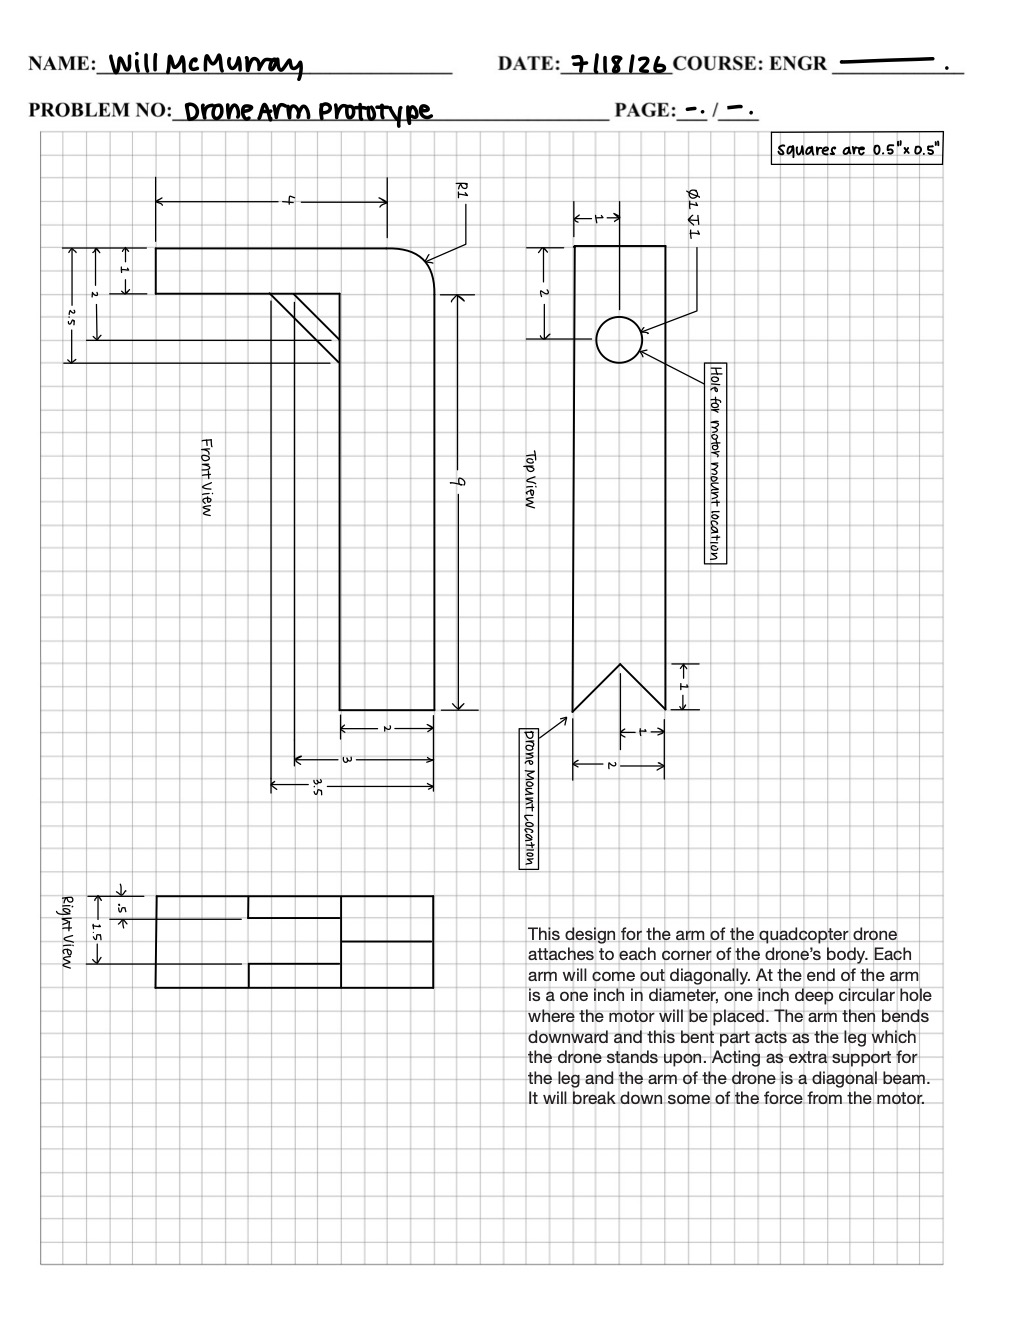

WRITEUP ABOUT DESIGN HERE

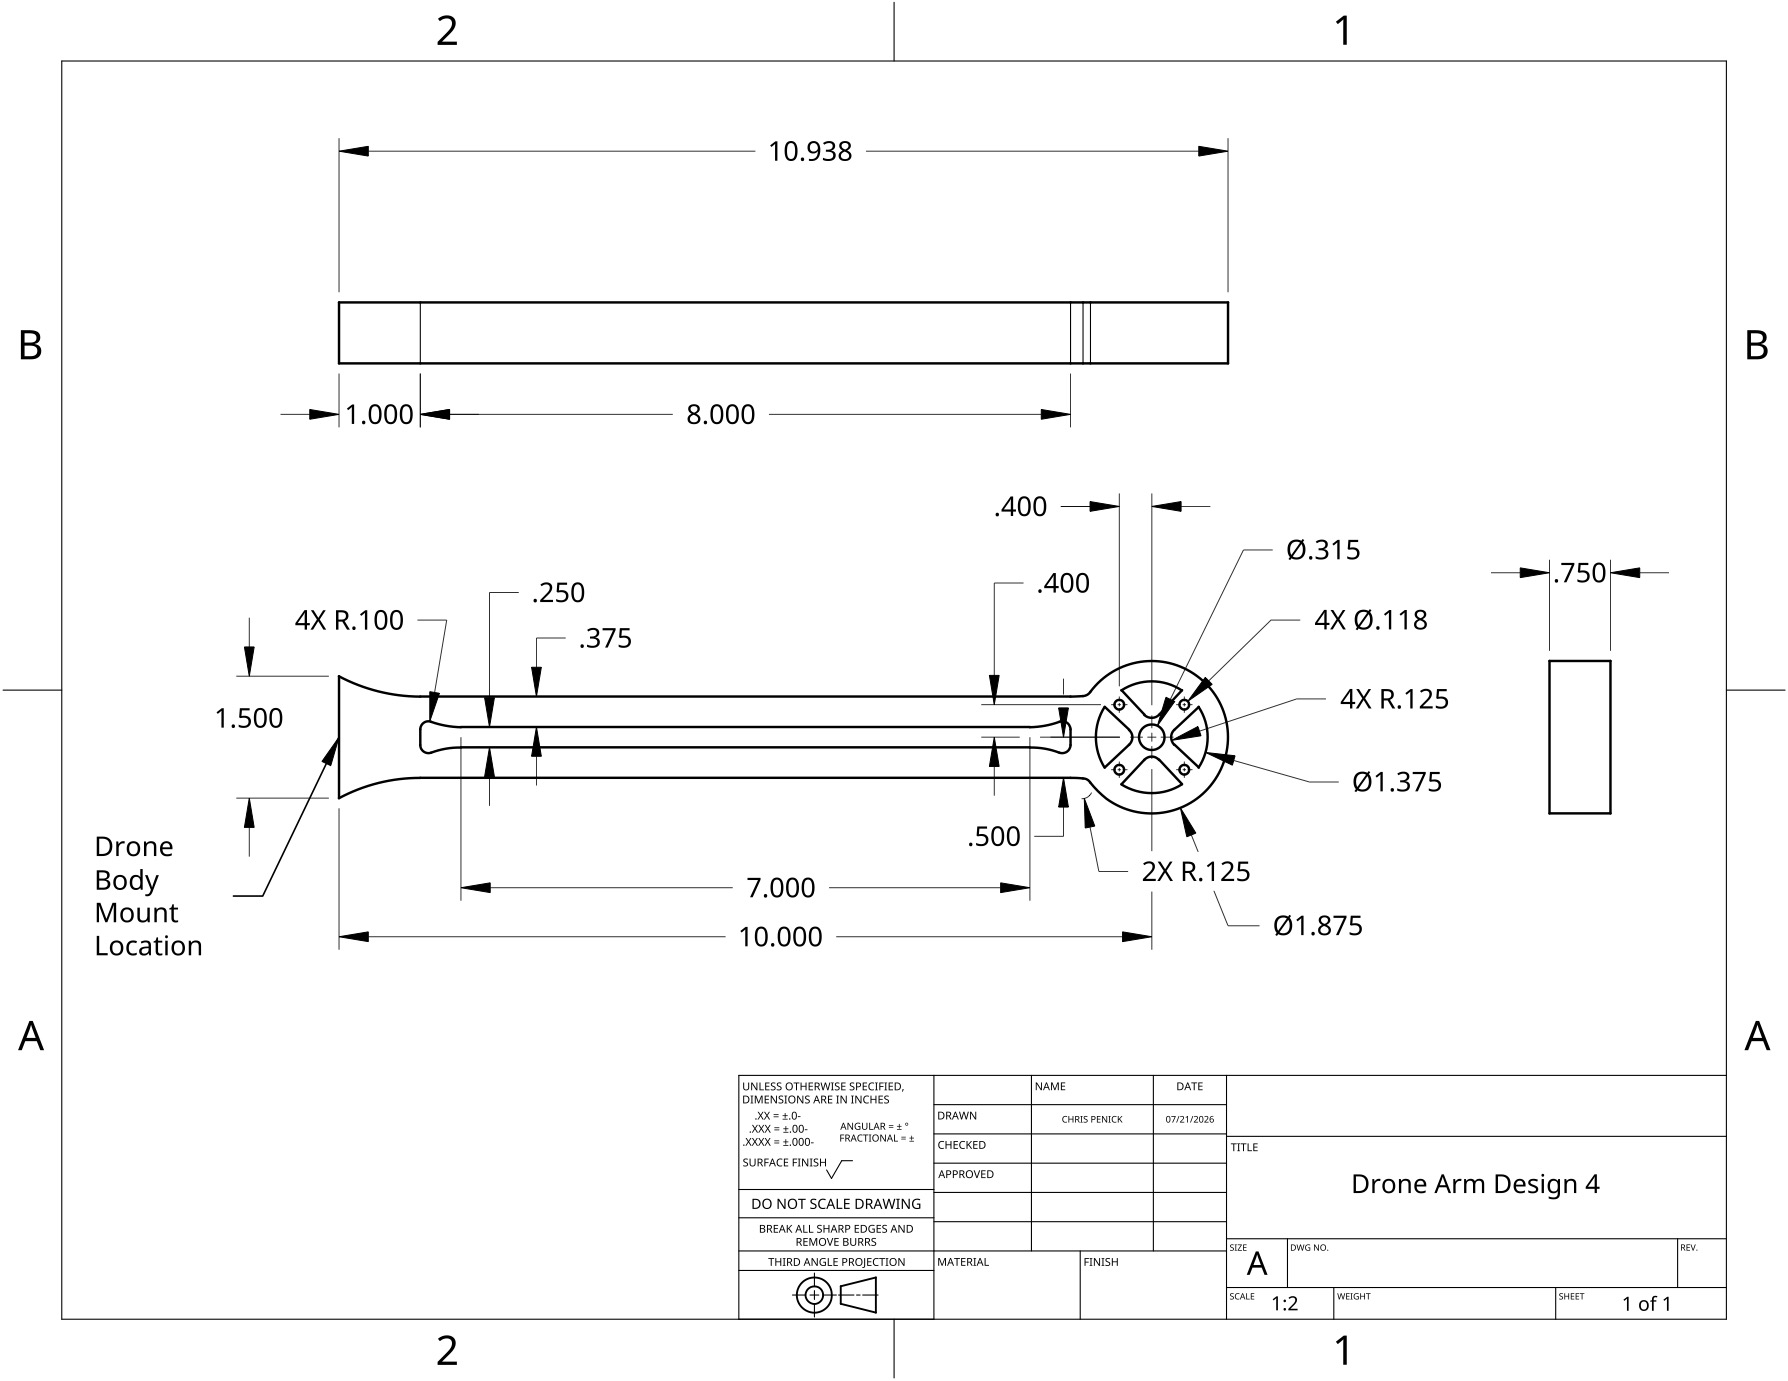

WRITEUP ABOUT DESIGN HERE

## Task 3: Perform thrust-to-weight analysis across all design and material options

Write a MATLAB function that will perform a thrust-to-weight analysis across all design and material options. This analysis will help you evaluate which drone arm design and which material optimizes payload capacity while meeting suggested safety requirements. 

- Your design must support a minimum payload of 0.5kg. 

- Your design must meet a thrust-to-weight ratio of at least 2:1 to ensure safe and stable flight. This safety standard is widely used in drone design. Conceptually, it means that the drone's maximum thrust must be at least twice its weight. This ensures stable hovering and maneuvering with a safety margin. Note that the thrust-to-weight safety margin is a system-level safety standard for drone flight that is distinct from the structural safety factor of the drone arms (which you will evaluate later through finite element analysis).

- Your goal is calculate maximum payload capacity for each design and material option (i.e. what is the heaviest payload your drone design could carry while still allowing the drone to safely take off?)

Ensure that the results of your analysis can be readily interpreted, e.g. in the form of a summary table or plot.

Note: if you have two drone arm designs, the expected output should be 12 payload capacity estimates (2 designs across 6 materials options).

% Insert your code in the spaces below (or make use of helper functions and indicate where
% they can be found). Ensure your code is well-documented.

% Hint: General suggested steps for the thrust-to-weight analysis-
% 1. Start with the known values (motor thrust capability and base drone
% mass without the payload). Note that for the base drone mass, you will
% need to calculate weight estimations for each proposed drone arm design
% and each  material option.
% 2. Add payload as a variable component of the weight.
% 3. Apply the requirement that total thrust must be at least twice the
% total weight of the drone.
% 4. Solve for maximum payload capacity

% Maximum total drone mass allowed by 2:1 thrust-to-weight ratio
maxAllowedTotalMass_kg = totalThrust_kg / requiredThrustToWeightRatio;

fprintf("Maximum allowed total drone mass = %.2f kg\n", maxAllowedTotalMass_kg);

Maximum allowed total drone mass = 2.00 kg


#### Select the files to analyze

Analyzing monitorMount-Body-dimtest.stl...

resultsTable = 6×5 table
               Material                OneArmMass_kg    TotalArmMass_kg    MaxPayload_kg    Design_Cost_USD
    _______________________________    _____________    _______________    _____________    _______________

    "Carbon Fiber Composite (CFRP)"       0.12171           0.48684           0.51316           1271.1     
    "Aluminum Alloy"                      0.20539           0.82155           0.17845           317.78     
    "Fiberglass Composite (GFRP)"         0.14453           0.57813           0.42187           635.57     
    "PLA Plastic"                        0.095087           0.38035           0.61965            148.3     
    "ABS Plastic"                        0.079873           0.31949           0.68051            148.3     
    "Wood (Birch)"                       0.04564

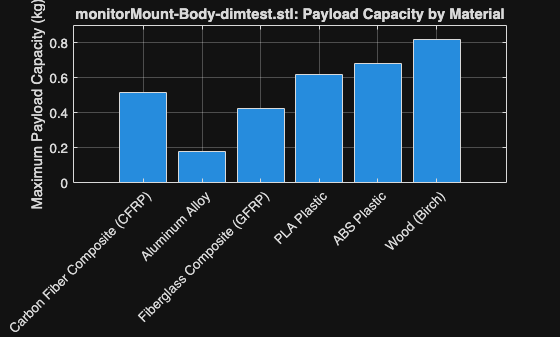

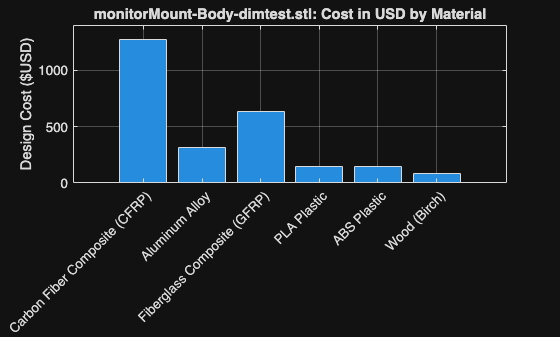

Analyzing monitorMount-Body.stl...

resultsTable = 6×5 table
               Material                OneArmMass_kg    TotalArmMass_kg    MaxPayload_kg    Design_Cost_USD
    _______________________________    _____________    _______________    _____________    _______________

    "Carbon Fiber Composite (CFRP)"       0.96356           3.8543            -2.8543           2533.4     
    "Aluminum Alloy"                        1.626           6.5041            -5.5041           633.36     
    "Fiberglass Composite (GFRP)"          1.1442           4.5769            -3.5769           1266.7     
    "PLA Plastic"                         0.75278           3.0111            -2.0111           295.57     
    "ABS Plastic"                         0.63234           2.5294            -1.5294           295.57     
    "Wood (Birch)"                        0.3613

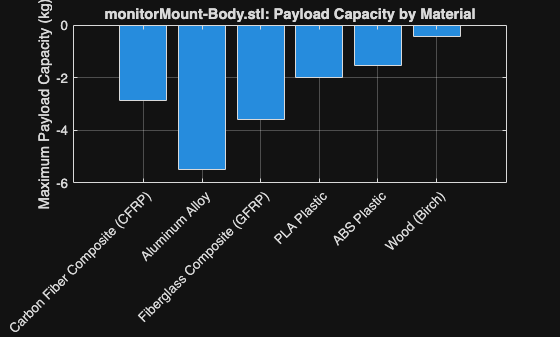

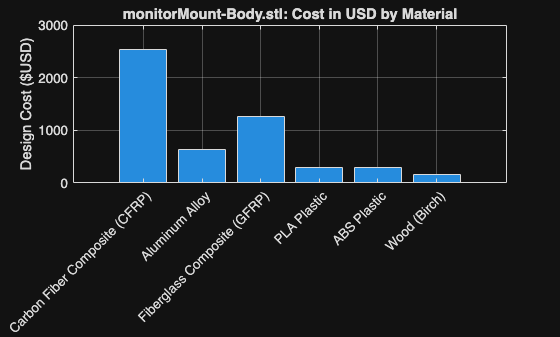

%Calculate the maximum payload of each material for each drone arm design
%fileName = "monitorMount-Body.stl"; %Choose the design file to analyze.

fileName_A = "monitorMount-Body.stl"; %File name of the main STL file to analyze and do FEA
fileName_B = "monitorMount-Body-dimtest.stl"; %File name of the STL file to compare with the main

fileName = [fileName_B, fileName_A];

    % Drone arm B tube refuses to load so I've kept the placeholder stl
    % files

for i = 1:length(fileName)
    fprintf("Analyzing " + fileName(i) + "...");
    model_fe = femodel(AnalysisType="structuralStatic", Geometry=fileName(i)); %Initializes the finite element model of the selected stl file
    model_mesh = createpde; %Initializes a partial differential equation geometry
    importGeometry(model_mesh, fileName(i)); %Initializes the partial differential equation geometry from the selected stl file
    model_mesh = generateMesh(model_mesh); %Initializes a mesh made of tris from the selected stl file
    
    %Create a table of payload data for every drone arm model
    armMass = materials.rho_kg_m3 * volume(model_mesh) * 1E-9; %Mass of one drone arm; STL units are in mm, so the exponential will convert mm^3 to m^3 (PLEASE VERIFY THIS!!!)
    payloadCapacity = maxAllowedTotalMass_kg - baseDroneMass_kg - (numArms * armMass); % Maximum payload capacity of the drone based on the material
    Design_Cost_USD = materials.cost_USD_per_m * (volume(model_mesh))^(1/3); %How much the design would cost per material
    

#### Thrust-to-Weight Analysis Results

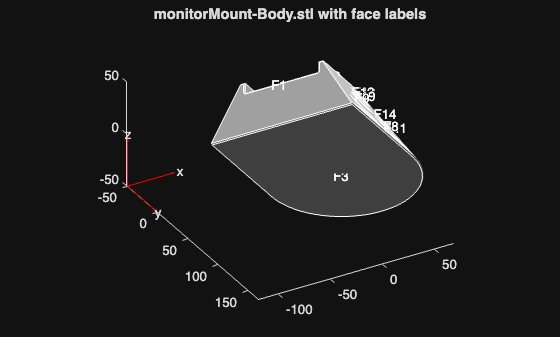

    resultsTable = table(materials.name, armMass, numArms * armMass, payloadCapacity, Design_Cost_USD,...
        'VariableNames', {'Material','OneArmMass_kg','TotalArmMass_kg','MaxPayload_kg','Design_Cost_USD'}) %Create a table summary of data for an stl model
    
    %Plot payload capacity of each arm design and material combination
    figure %Initialize figure
    
    bar(resultsTable.MaxPayload_kg) %Create bar graphs for the max payload values for each different material
    xticklabels(materials.name) %Define name of bar graphs
    xtickangle(45) %Rotate the bar graph names by 45 degrees
    
    ylabel("Maximum Payload Capacity (kg)") %y-axis label
    %xlabel("Material") %x-axis label

    
    chartTitle = fileName(i) + ": Payload Capacity by Material"; %Create custom title for each figure through string concatenation
    title(chartTitle); %Add custom title to current figure
    
    grid on
    
    %Plot cost for the drone arm per material 
    figure %Initialize figure
    
    bar(resultsTable.Design_Cost_USD) %Create bar graphs for the cost for each different material
    xticklabels(materials.name) %Define name of bar graphs
    xtickangle(45) %Rotate the bar graph names by 45 degrees
    
    ylabel("Design Cost ($USD)") %y-axis label
    %xlabel("Material") %x-axis label
    
    chartTitle = fileName(i) + ": Cost in USD by Material"; %Create custom title for each figure through string concatenation
    title(chartTitle); %Add custom title to current figure
    
    grid on
end

## Task 4: Perform finite element analysis across all design and material options

Perform finite element analysis (FEA) across all design and material options to evaluate the structural safety factor of your drone arm design. To simplify the task, you will perform the FEA only on a single drone arm.

Using a CAD software of your choice, first create a 3D model of one drone arm for each of your designs. Be sure your model can be exported as a STEP or STL file for analysis in MATLAB.

- Recommended CAD software options: Tinkercad, Onshape, Fusion 360, Solidworks (most have free versions)

Import your model into MATLAB and perform FEA. In your FEA model, you should model and apply two loads to the drone arm: upward thrust force from the motor and downward weight of the motor.

- Helpful resources: [online tutorial](https://matlabacademy.mathworks.com/details/introduction-to-finite-element-analysis-with-matlab/otmlfea), documentation for [Structural Mechanics](https://www.mathworks.com/help/pde/structural-mechanics.html) and [Partial Differentiation Equation Toolbox](https://www.mathworks.com/help/pde/index.html?s_tid=CRUX_lftnav), and [example workflow](https://www.mathworks.com/help/pde/ug/deflection-analysis-of-bracket-femodel.html)

For each design and material combination, you should report the overall maximum displacement, maximum stress, and factor of safety and include visualizations of the x-, y-, and z-displacement and Von Mises stress. Ensure that your results are presented for easy interpretation (e.g. present a table with numerical results, clearly labeled subplots for the visualizations).

- The factor of safety compares how strong a material is to how much stress it experiences, indicating whether a design is safe under the given loads. For this project use the equation: $\textrm{FoS}=\frac{\textrm{Material}\;\textrm{Yield}\;\textrm{Strength}\;\left(\textrm{Pa}\right)}{\textrm{Maximum}\;\textrm{von}\;\textrm{Mises}\;\textrm{Stress}}$. Yield strength indicates how much stress a given material can withstand before permanently deforming. Maximum von Mises stress (derived from your FEA model) is a measure of how much stress your design experiences under the applied loads.

- A typical engineering safety margin for FoS is ~1.5-2+

- This [example](https://www.mathworks.com/help/pde/ug/deflection-analysis-of-bracket-femodel.html) demonstrates the plots you are asked to include in your results

#### Modify view angle of visualizer

fileName = fileName(end); %To simplify the task, we're only performing FEA on the last drone arm design

% Import drone arm geometry into MATLAB, visualize the geometry to identify key faces (e.g. tip face)
viewAzimuth =30;
viewElevation = -30;
viewAngle = [viewAzimuth, viewElevation];
figureTitle = fileName + " with face labels";

figure
pdegplot(model_fe,FaceLabels='on') %Plots the finite element model with the specified view angle with face labels
view(viewAngle);
title(figureTitle)

#### View the visualized model and identify the static and loaded face

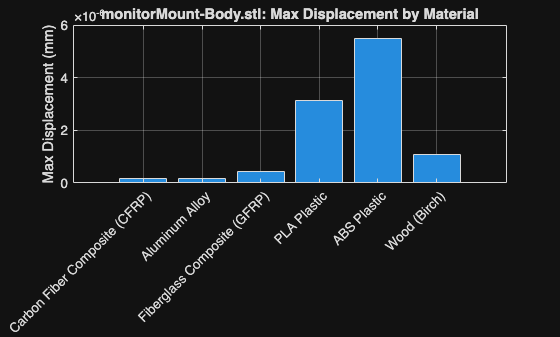

% Apply boundary conditions (fix base of arm where it would be attached to drone body)
 staticFace = 1; %Specifies the face or boundary condition where the drone arm will be attached to the drone body
 model_fe.FaceBC(staticFace) = faceBC(Constraint="fixed"); %Initializes the static face where the drone arm will be attached to the drone body in the finite element model

% Apply the upward thrust force (motor force); Define the thrust force, convert force to surface traction, apply surface traction to the appropriate face in the appropriate direction
loadFace = 4; %Specifies the face or boundary condition where the motor will be attached to the drone body
vectorMotorThrust = [0, 0, maxThrustPerMotor_N]; %Initializes the SurfaceTraction vector of the applied load

% Apply downward motor weight; Define motor weight, convert to traction, apply to the appropriate face in the appropriate direction
vectorMotorWeight = [0, 0, -motorMass_each_kg * g]; %Initializes the SurfaceTraction vector of the motor's weight
vectorMotor = vectorMotorThrust + vectorMotorWeight; %Combine the two loads into a single net traction rather than applying them separately

model_fe.FaceLoad(loadFace) = faceLoad(SurfaceTraction=vectorMotor); %Initializes the loading face where the motor will be attached to the drone body in the finite element model


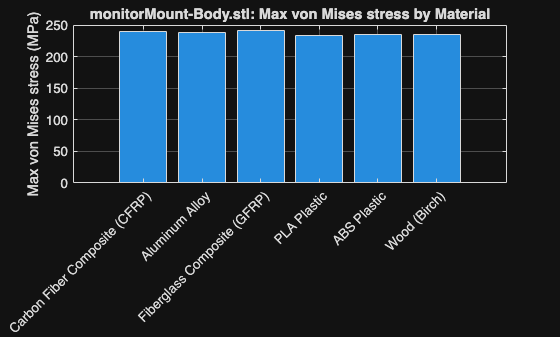

% Optional: include the force of gravity on the arm

%model_fe.FaceLoad = faceLoad(Gravity=g); This implementation breaks the FEA for some reason.

% Define material properties
for i = 1:length(resultsTable.Material) %Do FEM for all 6 materials for one drone design
    model_fe.MaterialProperties = materialProperties(YoungsModulus=materials.E_Pa(i), PoissonsRatio=materials.nu(i));
    model_mesh = generateMesh(model_fe); %Regenerates the mesh so it will have the FEM's material properties
    resultsFEA(i) = solve(model_mesh); %Solve the FEA model (using the solve function) and store the results for analysis
end

% Get numerical results; The results object generated above contain fields for displacement and stress.
% Report maximum displacement magnitude and maximum Von Mises stress for each material-design combination.
% Use the maximum Von Mises stress and given material yield strength to compute factor of safety for each material-design combination.
% Present your results for easy comparison (e.g. summary table or plot).


for i = 1:length(resultsTable.Material) 
    maxDisplacement(i) = max(resultsFEA(i).Displacement.Magnitude); %Find the max displacement of the specified material for the specified drone arm design in mm
    %I'm assuming this is in mm because I think the STL units are mm, but
    %please verify!
    maxVMS(i) = max(resultsFEA(i).VonMisesStress); %Find the max von Mises stress of the specified material for the specified drone arm design in MPA
    %I'm assuming that this is in MPA because I believe STL units are mm so
    %N / mm^3 is MPA, but please verify!
end

maxDisplacement = maxDisplacement(:); %Converts row vector into column vector so it can be added to a table later
maxVMS = maxVMS(:); %Converts row vector into column vector so it can be added to a table later
safetyFactor = materials.yieldStrength_Pa./maxVMS; %Calculates each material's safety factor for the specified drone arm design using the formula defined in the task prompt.


#### FEA Results

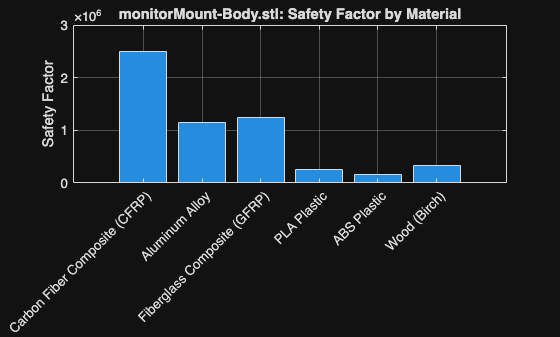

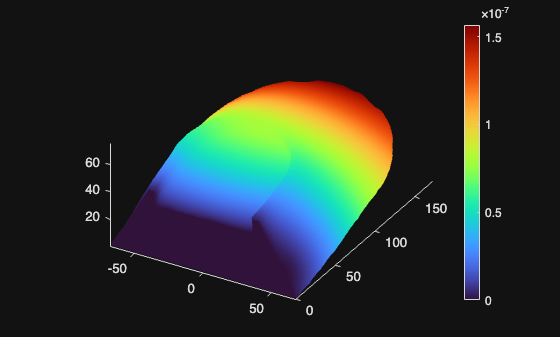

%Plot max displacement for the drone arm per material 
figure %Initialize figure

bar(maxDisplacement) %Create bar graphs for the cost for each different material
xticklabels(materials.name) %Define name of bar graphs
xtickangle(45) %Rotate the bar graph names by 45 degrees

ylabel("Max Displacement (mm)") %y-axis label
%xlabel("Material") %x-axis label

chartTitle = fileName + ": Max Displacement by Material"; %Create custom title for each figure through string concatenation
title(chartTitle); %Add custom title to current figure

grid on

%Plot max von Mises stress for the drone arm per material 
figure %Initialize figure


bar(maxVMS) %Create bar graphs for the cost for each different material
xticklabels(materials.name) %Define name of bar graphs
xtickangle(45) %Rotate the bar graph names by 45 degrees

ylabel("Max von Mises stress (MPa)") %y-axis label

resultsFEA_Table = 6×6 table
               Material                maxDisplacement_mm    maxVonMisesStress_MPa    safetyFactor    payloadCapacity_kg    Design_Cost_USD
    _______________________________    __________________    _____________________    ____________    __________________    _______________

    "Carbon Fiber Composite (CFRP)"        1.5648e-07               239.99             2.5001e+06           -2.8543             2533.4     
    "Aluminum Alloy"                        1.587e-07               237.62             1.1573e+06           -5.5041             633.36     
    "Fiberglass Composite (GFRP)"          4.3791e-07               240.76              1.246e+06           -3.5769             1266.7     
    "PLA Plastic"                          3.1232e-06             

%xlabel("Material") %x-axis label


Elapsed time is 51.636308 seconds.


chartTitle = fileName + ": Max von Mises stress by Material"; %Create custom title for each figure through string concatenation
title(chartTitle); %Add custom title to current figure

grid on

%Plot safety factor for the drone arm per material 
figure %Initialize figure

bar(safetyFactor) %Create bar graphs for the cost for each different material
xticklabels(materials.name) %Define name of bar graphs
xtickangle(45) %Rotate the bar graph names by 45 degrees

ylabel("Safety Factor") %y-axis label
%xlabel("Material") %x-axis label

chartTitle = fileName + ": Safety Factor by Material"; %Create custom title for each figure through string concatenation
title(chartTitle); %Add custom title to current figure

grid on

% Visualize your results; Create plots to visualize the x-, y-, and z-displacement and the von Mises stress.
% Hint: Use the Live Editor task "Visualize PDE Results" or the function pdeplot3D

#### Select material to visualize the PDE results

materialVisual = 1; %Since the Visualize PDE Results task doesn't account for an array of FEA results (it only shows the first entry), we'll have to specify which material's results we want to visualize.
resultsFEA_viz = resultsFEA(materialVisual); %Initialize the singular FEA result for visualization

% Data to visualize
meshData = resultsFEA_viz.Mesh;
nodalData = resultsFEA_viz.Displacement.Magnitude;
deformationData = resultsFEA_viz.Displacement;

% Create PDE result visualization
resultViz = pdeviz(meshData,abs(real(nodalData)), ...
    "DeformationData",deformationData, ...
    "DeformationScaleFactor",319199344.1138, ...
    "ColorLimits",[0 1.566e-07]);

% Clear temporary variables
clearvars meshData nodalData deformationData

#### Final Summary Table

resultsFEA_Table = table(materials.name, maxDisplacement, maxVMS, safetyFactor, payloadCapacity, Design_Cost_USD,...
    'VariableNames', {'Material','maxDisplacement_mm','maxVonMisesStress_MPa','safetyFactor','payloadCapacity_kg', 'Design_Cost_USD'}) %Create a table summary of data for the FEA

toc

## Interpretation of Results - Final Recommended Design Solution

Using the results of your thrust-to-weight analysis and finite element analysis, recommend a final drone arm design that meets all required constraints. Your recommendation should clearly identify the selected design (arm geometry and material choice), make use of quantitative results to justify your decisions, demonstrate that the design meets the constraints, explain the trade-offs considered, and include comparisons to alternative designs.

What are some limitations of your work?

What are practical next steps?